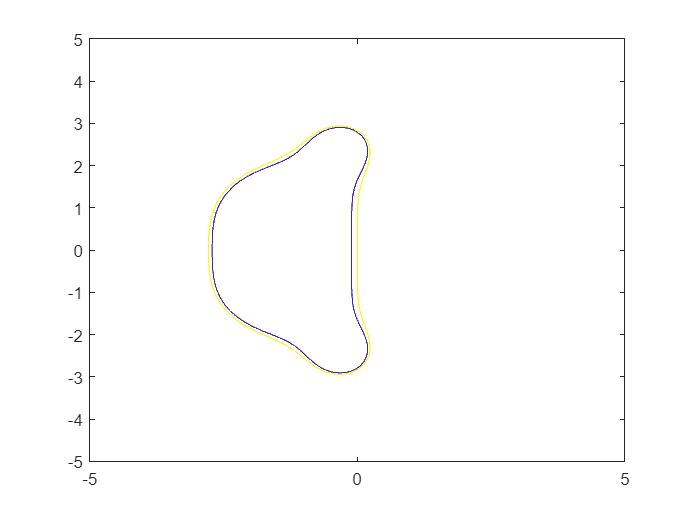

% syms k h
% syms z
% syms g(t,y) 
% g(t,y) = -k*y;
% syms k1(t,y) k2(t,y) k3(t,y) k4(t,y)
% k1(t,y) = g(t,y);
% k2(t,y) = g(t+h/2,y+k1*h/2);
% k3(t,y) = g(t+h/2,y+k2*h/2);
% k4(t,y) = g(t+h,y+h*k3);
% 
% step = (h/6)*(k1(t,y)+2*k2(t,y)+2*k3(t,y)+k4(t,y))-(h/6)*(k1(t,z)+2*k2(t,z)+2*k3(t,z)+k4(t,z));
% simplify(step);



clear i;
[X,Y] = meshgrid(-5:0.01:5,-5:0.01:5);
Mu = X+i*Y;
R = 1 + Mu + .5*Mu.^2 + (1/6)*Mu.^3 + (1/24)*Mu.^4;
Rhat = abs(R);
contour(X,Y,Rhat,[0.9,1]);
hold on

In this exercise we want to check the global error of applying RK4 to solve the equation


$$\begin{cases} 
y'(t) = -\lambda y\\
y(0) = 1
\end{cases}$$


for different values of $\lambda$ and step size $h$. The report will be a colormap representing the error at $t=1$ as a function of the complex quantity $\mu = h \lambda$.

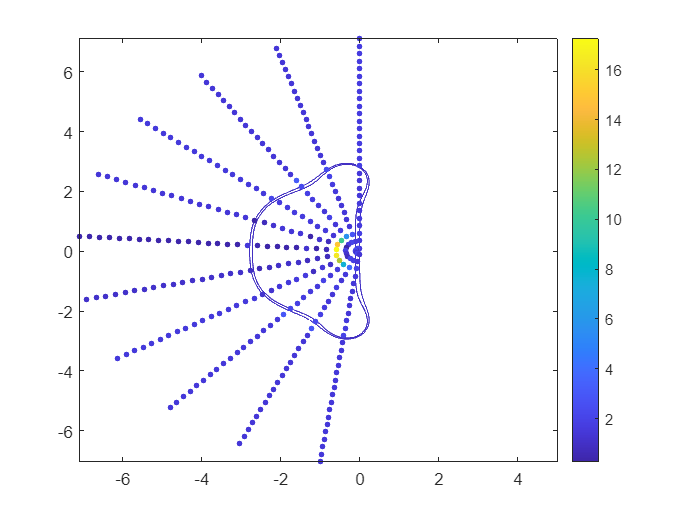

tic

for theta = pi/2:0.3:1.5*pi
    lambda = exp(i*theta);
    for h = 0.1:0.25:7.1
        mu_error = errorRK4(theta,h);
        scatter(h*cos(theta),h*sin(theta),10,mu_error,'filled')
        hold on
        colorbar
    end
end

toc

Elapsed time is 9.709251 seconds.


function error = errorRK4(theta,h)
    t = 0;
    y = 1;
    finaltime = 3;


    while t+h <= finaltime
        k1 = f(t,y,theta);
        k2 = f(t+h/2,y+h*k1/2,theta);
        k3 = f(t+h/2,y+h*k2/2,theta);
        k4 = f(t+h,y+h*k3,theta);
        y = y + (h/6) * (k1+2*k2+2*k3+k4);
        t = t+h;
    end

    if t ~= finaltime
        h = 1-t;
        k1 = f(t,y,theta);
        k2 = f(t+h/2,y+h*k1/2,theta);
        k3 = f(t+h/2,y+h*k2/2,theta);
        k4 = f(t+h,y+h*k3,theta);
        y = y + (h/6) * (k1+2*k2+2*k3+k4);
    end

    error = abs(exp(-(exp(1i*theta*finaltime)))-y);
end

function z = f(t,y,theta)
    z = -(exp(1i*theta))*y;
end